clc;clear
% d1 = load("matlab保存数据\52740.mat");  %120fs ，false ignore
% d2 = load("matlab保存数据\52777.mat");  %120fs， true  peak
% d1 = load("matlab保存数据\52786.mat");  %40fs ,  true peak
% d2 = load("matlab保存数据\52811.mat");  %40fs ,  false peak
% d2 = load("matlab保存数据\55992.mat");  %40fs ,  qs_mean rk4     ppt——I     
d1 = load("matlab保存数据\56041.mat");  %120fs ,  qs_mean rk4     ppt——I  
d2 = load("matlab保存数据\55978.mat");  %120fs ,  qs_mean rk4     ppt——I  

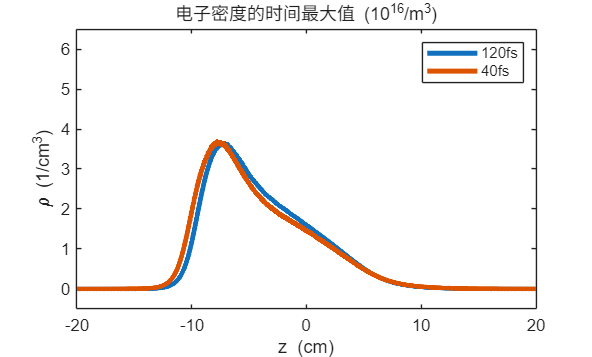


plot((d1.z_axis-0.2)*1e2,d1.rho_max_z/1e6/1e16,LineWidth=3);
hold on 
plot((d2.z_axis-0.2)*1e2,d2.rho_max_z/1e6/1e16,LineWidth=3);
hold off
xlim([-20,20]);ylim([-0.5,6.5])
legend('120fs','40fs')
xlabel('z  (cm)');ylabel('\rho (1/cm^3)');title('电子密度的时间最大值 (10^{16}/m^3)')

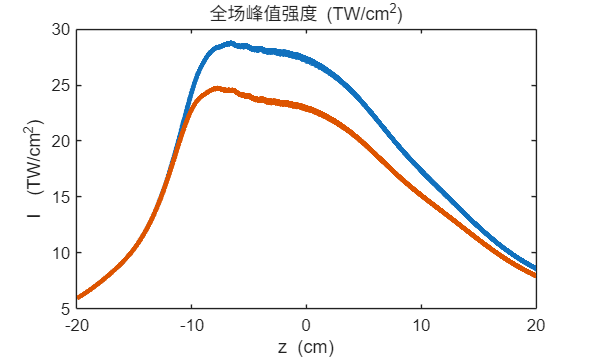

plot(1e2*(d1.z_axis-0.2),d1.I_max_z/1e4/1e12,LineWidth=3);
% xlim([0.7,1.2])
hold on 
plot(1e2*(d2.z_axis-0.2),d2.I_max_z/1e4/1e12,LineWidth=3);
hold off
xlabel('z  (cm)');ylabel('I  (TW/cm^2)');
title("全场峰值强度 (TW/cm^2)")

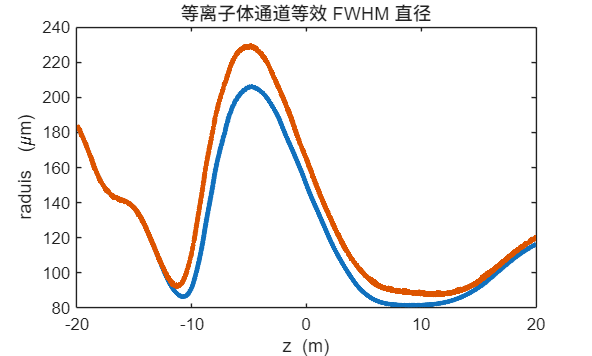

plot(1e2*(d1.z_axis-0.2),d1.fwhm_plasma_z*1e6,LineWidth=3)
hold on 
plot(1e2*(d2.z_axis-0.2),d2.fwhm_plasma_z*1e6,LineWidth=3)
hold off
% xlim([-12,13]);ylim([0,200])
xlabel('z  (m)');ylabel('raduis  (\mum)');title("等离子体通道等效 FWHM 直径")